%% Parameters (golden car)
clc
clear
close all

m_s = 3000;  % Sprung mass (masa del chasis por rueda) (kg)
k_s = 63.3*m_s;  % Spring stiffness (rigidez del resorte) (N/m)
c_s = 6*m_s;  % Damping coefficient (coeficiente de amortiguamiento del amortiguador) (Ns/m)
k_t = 653*m_s;  % Tire stiffness (rigidez del neumático) (N/m)
c_t = 0;  % Tire damping (Ns/m)
m_u = 0.15*m_s;  % (masa de la rueda) Unsprung mass (kg)


% 
%% Diseño del PID
% x = [pos_s
%      vel_s
%      pos_w
%      vel_w]

A_ss = [ 0 1 0 0
        -k_s/m_s -c_s/m_s k_s/m_s c_s/m_s
         0 0 0 1
        k_s/m_u c_s/m_u -(k_s+k_t)/m_u -c_s/m_u]; 

B_ss = [ 0
         -1/m_s
         0
         1/m_u];

C_ss = [1 0 -1 0];
D_ss = [0]';
     
H = tf(ss(A_ss, B_ss, C_ss, D_ss))

H =
 
        -0.002556 s^2 + 2.763e-18 s - 1.451
  -----------------------------------------------
  s^4 + 46 s^3 + 4839 s^2 + 2.612e04 s + 2.756e05
 
Continuous-time transfer function.



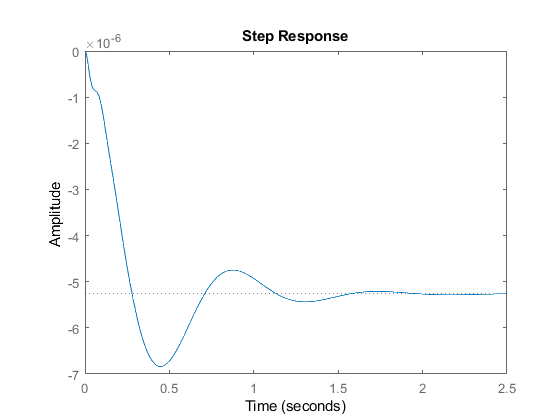

step(H)

stepinfo(H)

ans = struct with fields:
        RiseTime: 0.2246
    SettlingTime: 1.4353
     SettlingMin: -6.8378e-06
     SettlingMax: -4.7432e-06
       Overshoot: 29.8492
      Undershoot: 0
            Peak: 6.8378e-06
        PeakTime: 0.4468


%pidTuner(H, 'PID');

Bd = [0;1/m_s;0;0]

Bd = 	1.0e+-3 *

         0
    0.3333
         0
         0



Hd = tf(ss(A_ss, Bd, C_ss, D_ss))

Hd =
 
        0.0003333 s^2 + 5.921e-19 s + 1.451
  -----------------------------------------------
  s^4 + 46 s^3 + 4839 s^2 + 2.612e04 s + 2.756e05
 
Continuous-time transfer function.



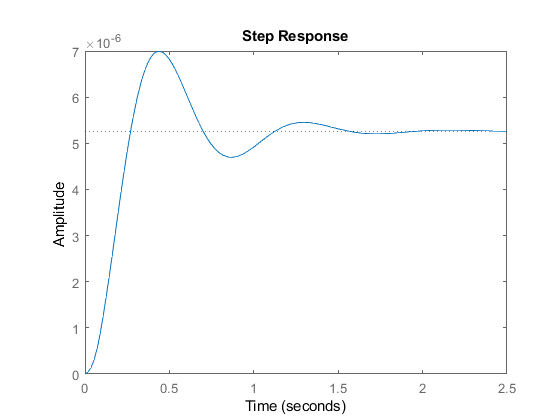

step(Hd)

kp = controller.Kp * 0.6

kp = -3.0809e+05

ki = controller.Ki * 0.8

ki = -1.3697e+06

kd = controller.Kd * 1

kd = -3.8500e+04

% Kp = -308085.637751808;
% Ki = -1.369657386898872e+06;
% Kd = -3.849979852092184e+04;

C= tf([kd,kp,ki],[1,0])

C =
 
  -3.85e04 s^2 - 3.081e05 s - 1.37e06
  -----------------------------------
                   s
 
Continuous-time transfer function.




sys_controlado = feedback(H*C,1)

sys_controlado =
 
    98.39 s^4 + 787.3 s^3 + 5.937e04 s^2 + 4.471e05 s + 1.988e06
  -----------------------------------------------------------------
  s^5 + 144.4 s^4 + 5626 s^3 + 8.549e04 s^2 + 7.226e05 s + 1.988e06
 
Continuous-time transfer function.



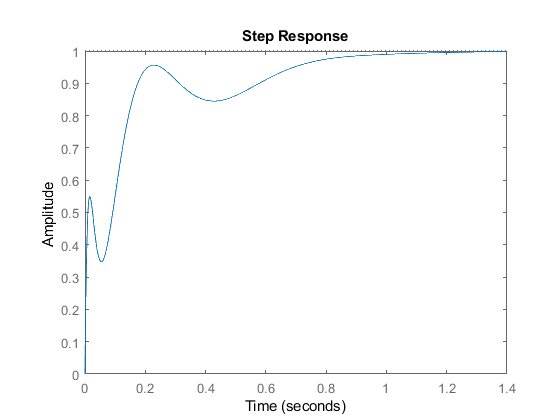

step(sys_controlado)

stepinfo(sys_controlado)

ans = struct with fields:
        RiseTime: 0.1737
    SettlingTime: 0.8426
     SettlingMin: 0.8449
     SettlingMax: 0.9984
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9984
        PeakTime: 1.4278


sys_perturbado = feedback(1,C*H)*Hd

sys_perturbado =
 
                                                                                                     
            0.0003333 s^7 + 0.01533 s^6 + 3.064 s^5 + 75.46 s^4 + 7113 s^3 + 3.79e04 s^2 + 3.999e05 s
                                                                                                     
  --------------------------------------------------------------------------------------------------------------
                                                                                                                
  s^9 + 190.4 s^8 + 1.711e04 s^7 + 1.069e06 s^6 + 3.592e07 s^5 + 6.356e08 s^4 + 7.371e09 s^3 + 5.205e10 s^2     
                                                                                                                
                                                                                          + 2.51e11 s + 5.477e11
                                                                                                              

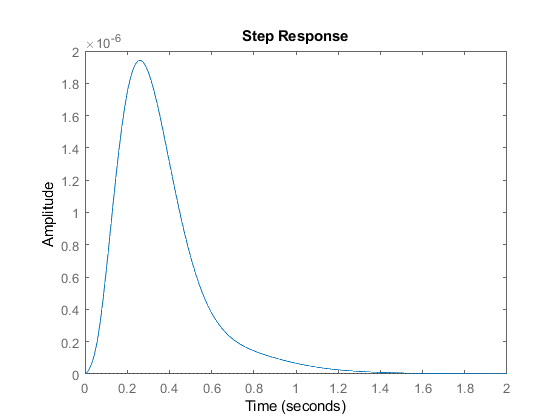

step(sys_perturbado)

stepinfo(sys_perturbado)

ans = struct with fields:
        RiseTime: 0
    SettlingTime: 1.1177
     SettlingMin: 2.0307e-10
     SettlingMax: 1.9415e-06
       Overshoot: Inf
      Undershoot: 0
            Peak: 1.9415e-06
        PeakTime: 0.2612


I-PD controller

Gi = tf(ki,[1 0])

Gi =
 
  -1.37e06
  --------
     s
 
Continuous-time transfer function.



Gpd = tf([kd kp],1)

Gpd =
 
  -3.85e04 s - 3.081e05
 
Continuous-time transfer function.



sys_con_I_PD = feedback(H,(Gi+Gpd))*Gi

sys_con_I_PD =
 
                  3500 s^3 - 3.785e-12 s^2 + 1.988e06 s
  ---------------------------------------------------------------------
  s^6 + 144.4 s^5 + 5626 s^4 + 8.549e04 s^3 + 7.226e05 s^2 + 1.988e06 s
 
Continuous-time transfer function.



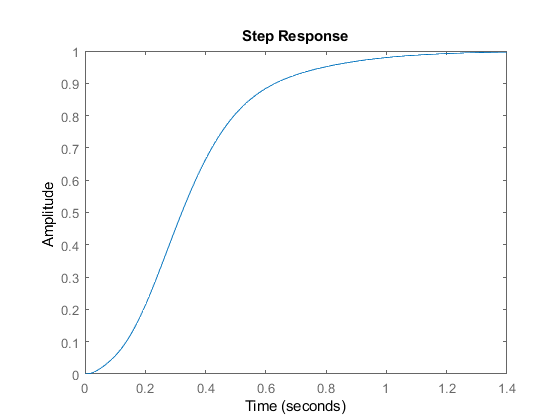

step(sys_con_I_PD)

stepinfo(sys_con_I_PD)

ans = struct with fields:
        RiseTime: 0.4944
    SettlingTime: 1.0028
     SettlingMin: 0.9031
     SettlingMax: 0.9992
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9992
        PeakTime: 1.7115


sys_per_I_PD = feedback(1, H*(Gi+Gpd))*Hd

sys_per_I_PD =
 
                                                                                                     
            0.0003333 s^7 + 0.01533 s^6 + 3.064 s^5 + 75.46 s^4 + 7113 s^3 + 3.79e04 s^2 + 3.999e05 s
                                                                                                     
  --------------------------------------------------------------------------------------------------------------
                                                                                                                
  s^9 + 190.4 s^8 + 1.711e04 s^7 + 1.069e06 s^6 + 3.592e07 s^5 + 6.356e08 s^4 + 7.371e09 s^3 + 5.205e10 s^2     
                                                                                                                
                                                                                          + 2.51e11 s + 5.477e11
                                                                                                                

step(sys_per_I_PD)

stepinfo(sys_per_I_PD)

ans = struct with fields:
        RiseTime: 0
    SettlingTime: 1.1177
     SettlingMin: 2.0307e-10
     SettlingMax: 1.9415e-06
       Overshoot: Inf
      Undershoot: 0
            Peak: 1.9415e-06
        PeakTime: 0.2612


Esfuerzo de control EJ3

esf_con = feedback(1,H*(Gi+Gpd))*Gi

esf_con =
 
  -1.37e06 s^5 - 6.3e07 s^4 - 6.627e09 s^3 - 3.578e10 s^2 - 3.774e11 s
  ---------------------------------------------------------------------
  s^6 + 144.4 s^5 + 5626 s^4 + 8.549e04 s^3 + 7.226e05 s^2 + 1.988e06 s
 
Continuous-time transfer function.



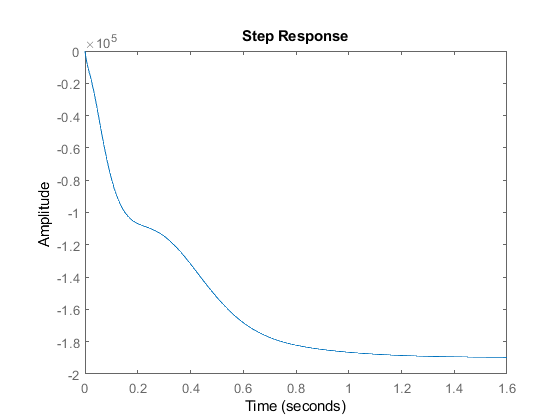

step(esf_con)

stepinfo(esf_con)

ans = struct with fields:
        RiseTime: 0.5990
    SettlingTime: 0.9704
     SettlingMin: -1.8981e+05
     SettlingMax: -1.7108e+05
       Overshoot: 0
      Undershoot: 0
            Peak: 1.8981e+05
        PeakTime: 1.8055


Control en espacio de estados

%pzmap(H)
%grid on
z1 = 1/sqrt(2);
wn1 = 50;
p1 = [1 2*z1*wn1 wn1^2];
polos1 = roots(p1)

polos1 =  -35.3553 +35.3553i
 -35.3553 -35.3553i


z2 = 1;
wn2 = 5;
p2 = [1 2*z2*wn2 wn2^2];
polos2 = roots(p2)

polos2 =     -5
    -5


poloint = -3*z1*wn1

poloint = -106.0660

polos = [polos1;polos2;poloint]

polos = 	1.0e+02 *

  -0.3536 + 0.3536i
  -0.3536 - 0.3536i
  -0.0500 + 0.0000i
  -0.0500 + 0.0000i
  -1.0607 + 0.0000i


Aaug = [A_ss [0;0;0;0]; C_ss 0]

Aaug = 	1.0e+03 *

         0    0.0010         0         0         0
   -0.0633   -0.0060    0.0633    0.0060         0
         0         0         0    0.0010         0
    0.4220    0.0400   -4.7753   -0.0400         0
    0.0010         0   -0.0010         0         0


Baug = [B_ss;0]

Baug =          0
   -0.0003
         0
    0.0022
         0


Kaug = acker(Aaug,Baug,polos)

Kaug = 	1.0e+06 *

   -1.8097   -0.2286    2.8579    0.0291   -4.5683


K = Kaug(1, 1:end-1)

K = 	1.0e+06 *

   -1.8097   -0.2286    2.8579    0.0291


ki_ss = Kaug(end)

ki_ss = -4.5683e+06

M = A_ss - B_ss*K;

X = C_ss * (M \ B_ss) % M \B es equivalente a inv(M)*Bu pero más estable

X = 5.0010e-07


kr = -1 / X 

kr = -1.9996e+06

LQR

Aaug = [A_ss [0;0;0;0]; C_ss 0]

Aaug = 	1.0e+03 *

         0    0.0010         0         0         0
   -0.0633   -0.0060    0.0633    0.0060         0
         0         0         0    0.0010         0
    0.4220    0.0400   -4.7753   -0.0400         0
    0.0010         0   -0.0010         0         0


Baug = [B_ss;0]

Baug =          0
   -0.0003
         0
    0.0022
         0


a1 = 10;
a2 = 10;
dx_max = 0.01;
e_int_max = 10;
umax = 40000;
ro = 1000;
Qy = [a1/dx_max^2 0; 0 a2/e_int_max^2]

Qy = 	1.0e+05 *

    1.0000         0
         0    0.0000


Qx = [C_ss 0; 0 0 0 0 1]'*Qy*[C_ss 0; 0 0 0 0 1]

Qx = 	1.0e+05 *

    1.0000         0   -1.0000         0         0
         0         0         0         0         0
   -1.0000         0    1.0000         0         0
         0         0         0         0         0
         0         0         0         0    0.0000


Qu = ro/umax^2

Qu = 6.2500e-07

K_lqr = lqr(Aaug,Baug,Qx,Qu)

K_lqr = 	1.0e+05 *

   -2.5293   -0.2346    1.6232    0.0045   -0.0040


K = K_lqr(1,1:end-1)

K = 	1.0e+05 *

   -2.5293   -0.2346    1.6232    0.0045


ki_ss = K_lqr(end)

ki_ss = -400.0000

M_lqr = A_ss - B_ss*K;
X_lqr = C_ss * (M_lqr \ B_ss) % M \B es equivalente a inv(M)*Bu pero más estable

X_lqr = 2.2582e-06


kr = -1 / X_lqr

kr = -4.4283e+05